clear

addpath("functions\")

#### Add defect to plate

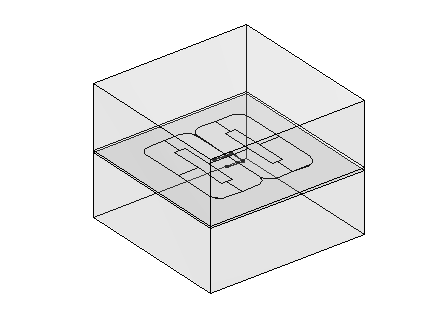

Model = myModel;
freqs = [1000]; % (Hz)
mesh_size = 4; % 1:finest 9:coarsest

 Model = ComsolInterface('Build', Model);

ComsolInterface('AddCircularDefect', Model, -0.008, -0.008, 0.002,    -0.0000, -0.0010)
ComsolInterface('AddCircularDefect', Model,  0.008, -0.008, 0.002,    -0.0005, -0.0015)
ComsolInterface('AddCircularDefect', Model,  0.008,  0.008, 0.002,    -0.0005, -0.0020)
ComsolInterface('AddCircularDefect', Model, -0.008,  0.008, 0.002,    -0.0010, -0.0020)

figure
ComsolInterface('PlotGeometry', Model)

#### Compute fields

x_s = Model.sensors.positions(1,:);
y_s = Model.sensors.positions(2,:);
z_s = Model.sensors.positions(3,:);

delta_B = zeros(length(freqs), size(Model.sensors.positions,2));
for i = 1:length(freqs)
    tic
    ComsolInterface('Solve', Model, freqs(i), mesh_size, true);
    [Bx, By, Bz] = ComsolInterface('EvaluateField', Model, {'Bx' 'By' 'Bz'}, x_s,y_s,z_s);
    B1 = dot([Bx;By;Bz], Model.sensors.axes);
    fprintf("Solve %g Hz with defects took %.2f seconds\n", freqs(i), toc)

    tic
    ComsolInterface('Solve', Model, freqs(i), mesh_size, false);
    [Bx, By, Bz] = ComsolInterface('EvaluateField', Model, {'Bx' 'By' 'Bz'}, x_s,y_s,z_s);
    B2 = dot([Bx;By;Bz], Model.sensors.axes);
    fprintf("Solve %g Hz without defects took %.2f seconds\n", freqs(i), toc)

    delta_B(i,:) = B1 - B2;
end

Solve 1000 Hz with defects took 173.65 seconds


Solve 1000 Hz without defects took 170.67 seconds



clear x_s y_s z_s i B1 B2

#### Export sensor data

fname = sprintf('data/delta-B_%s.txt', datetime('now','Format','MMdd-HHmm'));

fid = fopen(fname, 'w');

global defects
for i = 1:length(defects)
    fprintf(fid, '%% defect %s\n', jsonencode(defects{i}));
end
for i = 1:length(freqs)
    fprintf(fid, '%% frequency %g Hz\n', freqs(i));
    fprintf(fid, '%s\n', num2str(delta_B(i,:)));
end

fclose(fid);

clear fname fid i